# Initial Settings

clc;clear;
n = 15;       % Changable, n >= 2 and must be an integer
area_num = 1.5*n^2+ 2.5*n - 1;
pr = 0.9;    % Changable, 0 < pr < 1
MB = 1.2;      % Changable, MB > 1
gamma = 1.4;
syms Me_sym
eq = ((1 + (gamma - 1)/2*Me_sym^2)^(-gamma/(gamma-1))) / ((1 + (gamma - 1)/2*MB^2)^(-gamma/(gamma-1))) - pr;
eq = matlabFunction(eq);
[Me,~] = fzero(eq,MB);
omegaB = solve_omega(MB,gamma);
omegae = solve_omega(Me,gamma);
theta_total = omegaB - omegae;
dtheta = theta_total/n;       % rad
AREA = struct('number',{},'theta',{},'omega',{},'M',{},'I',{},'II',{},'mu',{});

## Solve for Numbers

numbers = 1:area_num;

## Solve for Thetas

for i = 1:n
    thetas(i) = i*dtheta;
    for j = 0:n-i
        thetas(i*(n+1)+j) = j*dtheta;
    end
    for j = n-i+1:n
        thetas(i*(n+1)+j) = (-j-2*i+2*n)*dtheta;
    end
end
num_flag = n;
num_3 = n^2 + 2*n + 1;
while num_flag > 1
    for k = 0:num_flag - 1
        thetas(num_3) = -k*dtheta;
        num_3 = num_3 + 1;
    end
    num_flag = num_flag - 1;
end

## Solve for Omegas & Ms & (I,II)s

for i = 1:n
    p_rank(i) = i;
    p_rank(i*(n+1)) = 2*i;
    for j = 1:n-i
        p_rank(i*(n+1)+j) = 2*i + j;
    end
    for j = n-i+1:n
        p_rank(i*(n+1)+j) = 2*n - j;
    end
end
num_flag = n;
num_3 = n^2 + 2*n + 1;
while num_flag > 1
    p_rank(num_3) = 2*(num_flag-1);
    for k = 1:num_flag - 1
        num_3 = num_3 + 1;
        p_rank(num_3) = 2*(num_flag-1) - k;
    end
    num_3 = num_3 + 1;
    num_flag = num_flag - 1;
end
for i = 1:area_num
    omegas(i) = -dtheta*p_rank(i) + omegaB;
    Ms(i) = solve_M(omegas(i),gamma);
    Is(i) = rad2deg(thetas(i) + omegas(i))/2 + 500;
    IIs(i) = rad2deg(thetas(i) - omegas(i))/2 + 500;
end

## Solve for Mach Angles & Wave Angles

for i = 1:area_num
    mus(i) = asin(1/Ms(i));
end
wave_angles = zeros(n,4);
SB_angles = zeros(1,n+1);
wave_angles(1,1) = asin(1/MB);
for j = 2:n
    wave_angles(j,1) = thetas(j-1) + mus(j-1);
end
for k = 1:n
    wave_angles(k,2) = pi + thetas((n+1)*k-n) - mus((n+1)*k-n);
    wave_angles(k,3) = thetas((n+1)*k+n-1) + mus((n+1)*k+n-1);
end
wave_angles(1,4) = pi + thetas(n^2+n+1) - mus(n^2+n+1);
for l = 1:n+1
    SB_angles(1,l) = thetas(l*(n+1)-1);
end

## Fill in the Output

AREA(1).number = 1;
AREA(1).theta = 0;
AREA(1).omega = omegaB;
AREA(1).M = MB;
AREA(1).I = rad2deg(0 + omegaB)/2+ 500;
AREA(1).II = rad2deg(0 - omegaB)/2+ 500;
AREA(1).mu = wave_angles(1,1);
AREA(area_num+2).number = area_num+2;
AREA(area_num+2).theta = 0;
AREA(area_num+2).omega = omegaB;
AREA(area_num+2).M = MB;
AREA(area_num+2).I = rad2deg(0 + omegaB)/2+ 500;
AREA(area_num+2).II = rad2deg(0 - omegaB)/2+ 500;
AREA(area_num+2).mu = wave_angles(1,1);
for i = 1:area_num
    AREA(i+1).number = numbers(i) + 1;
    AREA(i+1).theta = thetas(i);
    AREA(i+1).omega = omegas(i);
    AREA(i+1).M = Ms(i);
    AREA(i+1).I = Is(i);
    AREA(i+1).II = IIs(i);
    AREA(i+1).mu = mus(i);
end

## Plot the Graph

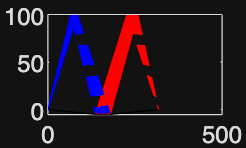

plot([0 500],[100 100],'-k');hold on;
x2(1)=0;y2(1)=0;
for i=2:n+1
    x1(i)=100/tan(wave_angles(i-1,1));
    y1(i)=100;
    plot([0 x1(i)],[0 y1(i)],'-b');hold on;

    x2(i)=x1(i)+(y1(i)-y2(i-1)-tan(SB_angles(i-1))*(x1(i)-x2(i-1)))/(tan(SB_angles(i-1))-tan(wave_angles(i-1,2)));
    y2(i)=y2(i-1)+(x2(i)-x2(i-1))*tan(SB_angles(i-1));
    plot([x1(i) x2(i)],[y1(i) y2(i)],'--b');hold on;
    plot([x2(i-1) x2(i)],[y2(i-1) y2(i)],'-k');hold on;

    x3(i)=x2(i)+(100-y2(i))/tan(wave_angles(i-1,3));
    y3(i)=100;
    plot([x2(i) x3(i)],[y2(i) y3(i)],'-r');hold on;
end
x4(2)=x3(2)+(y3(2)-y2(n+1)-tan(SB_angles(n+1))*(x3(2)-x2(n+1)))/(tan(SB_angles(n+1))-tan(wave_angles(1,4)));
y4(2)=y2(n+1)+(x4(2)-x2(n+1))*tan(SB_angles(n+1));
plot([x2(n+1) x4(2)],[y2(n+1) y4(2)],'-k');hold on;
for i=2:n+1
    plot([x3(i) x4(2)],[y3(i) y4(2)],'--r');hold on;
end

## Functions

function omega = solve_omega(M,gamma)
    omega = ((gamma+1)/(gamma-1))^0.5*atan(((gamma-1)/(gamma+1)*(M^2-1))^0.5) - atan((M^2-1)^0.5);
end

function M = solve_M(omega,gamma)
    syms M_sym
    eq = ((gamma+1)/(gamma-1))^0.5*atan(((gamma-1)/(gamma+1)*(M_sym^2-1))^0.5) - atan((M_sym^2-1)^0.5) - omega;
    eq = matlabFunction(eq);
    [M,~] = fzero(eq,[1.0001,10000]);
end